# rojTop view plot

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
SavingPath = './GraphForPaper/'
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
for i = 2:2
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        
        z = traj(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj = traj(1:top,:);
        
        
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        %ax(i) = subplot(3,4,i);
        
        %plot(x,y);
        
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        y(end) = nan;
        patch(x,y,c,'FaceColor','none','EdgeColor','interp');
        
        
        hold on;
        
        plot(xline,yline,'-k');
        
        %hold on;
        %quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        xlim([-10, 10]);
        ylim([-10, 10]);
        colorbar;
        %xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d); FileName{i}})
        xlabel(FileName{i});
        box on;
        caxis([0, 1250]);
        yticks([-10 0 10]);
        xticks([-10 0 10]);
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        ax = gca;
        ax.FontSize = 24; 
        save(path,'traj3D','Plane');
        set(gcf,'position',[0,0,800,800]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'.fig'])
    end
end




figure('visible','on');
for i = 13:24
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        
        z = traj(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj = traj(1:top,:);
        
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        %ax(i) = subplot(3,4,i);
        
        %plot(x,y);
        
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        y(end) = nan;
        patch(x,y,c,'FaceColor','none','EdgeColor','interp');
        
        
        hold on;
        
        plot(xline,yline,'-k');
        
        %hold on;
        %quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        xlim([-10, 10]);
        ylim([-10, 10]);
        colorbar;
        %xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d); FileName{i}})
        xlabel(FileName{i});
        box on;
        caxis([0, 1250]);
        yticks([-10 0 10]);
        xticks([-10 0 10]);
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        ax = gca;
        ax.FontSize = 24; 
        save(path,'traj3D','Plane');
        set(gcf,'position',[0,0,800,800]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'.fig'])
    end
end

figure('visible','on');

for i = 25:28
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        
        z = traj(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj = traj(1:top,:);
        
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        %ax(i) = subplot(3,4,i);
        
        %plot(x,y);
        
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        y(end) = nan;
        patch(x,y,c,'FaceColor','none','EdgeColor','interp');
        
        
        hold on;
        
        plot(xline,yline,'-k');
        
        %hold on;
        %quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        xlim([-10, 10]);
        ylim([-10, 10]);
        colorbar;
        %xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d); FileName{i}})
        xlabel(FileName{i});
        box on;
        caxis([0, 1250]);
        yticks([-10 0 10]);
        xticks([-10 0 10]);
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        ax = gca;
        ax.FontSize = 24; 
        save(path,'traj3D','Plane');
        set(gcf,'position',[0,0,800,800]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'.fig'])
    end
end
figure('visible','on');

for i = 29:35
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        
        z = traj(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj = traj(1:top,:);
        
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        %ax(i) = subplot(3,4,i);
        
        %plot(x,y);
        
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        y(end) = nan;
        patch(x,y,c,'FaceColor','none','EdgeColor','interp');
        
        
        hold on;
        
        plot(xline,yline,'-k');
        
        %hold on;
        %quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        xlim([-10, 10]);
        ylim([-10, 10]);
        colorbar;
        %xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d); FileName{i}})
        xlabel(FileName{i});
        box on;
        caxis([0, 1250]);
        yticks([-10 0 10]);
        xticks([-10 0 10]);
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        ax = gca;
        ax.FontSize = 24; 
        save(path,'traj3D','Plane');
        set(gcf,'position',[0,0,800,800]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'.fig'])
    end
end

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
SavingPath = './GraphForPaper/'
figure('visible','on');
for i = 1:5
    clf
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj = data.traj3D;
        
        z = traj(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj = traj(1:top,:);
        
        % calculate pca 
        L = length(traj);
        [n,V,p] = affine_fit(traj(round(L/4):round(L/4*3),1:3));
        a = n(1); b = n(2); d = a * p(1) + b * p(2); 
        % draw arrow for view point
        slope = -a/b; AntiSlope = -1/slope;
        LengthUnit = sqrt(1 + (1/AntiSlope)^2);
        xline = -10:1:10;
        yline = (d - a * xline)/b; 
        % pca finished
        x = traj(:,1);
        y = traj(:,2);
        %ax(i) = subplot(3,4,i);
        
        %plot(x,y);
        
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        y(end) = nan;
        patch(x,y,c,'FaceColor','none','EdgeColor','interp');
        
        
        hold on;
        
        plot(xline,yline,'-k');
        
        %hold on;
        %quiver(p(1),p(2),-5/AntiSlope/LengthUnit,- 5/LengthUnit,'AutoScale','off','MaxHeadSize',2,'color','r');
        axis equal;
        xlim([-10, 10]);
        ylim([-10, 10]);
        colorbar;
        %xlabel({['foil: ', num2str(foil(i))]; sprintf('%f x + %f y = % f', a, b ,d); FileName{i}})
        %xlabel(FileName{i});
        box on;
        caxis([0, 1250]);
        yticks([-10 0 10]);
        xticks([-10 0 10]);
        %save data
        traj3D = traj; 
        Plane = [a,b,d];
        ax = gca;
        ax.FontSize = 24; 
        save(path,'traj3D','Plane');
        set(gcf,'position',[0,0,800,800]);
        set(gcf,'color','w');
        savefig([SavingPath,'NewAirBubbleCase',num2str(i),'.fig'])
    end
end

## Sideview projection plot

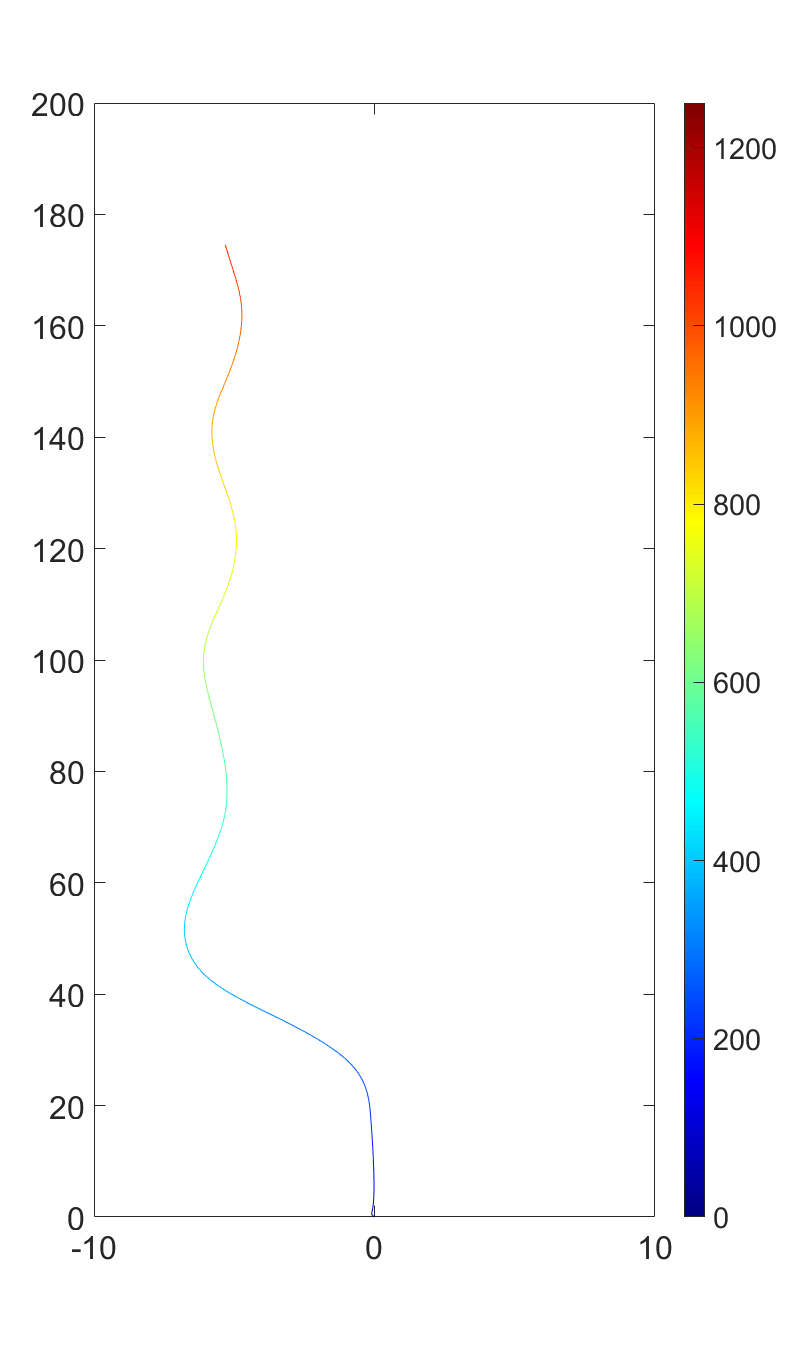

d = 4.4471

d = -0.1038

d = -1.2963

d = 0.8499

d = 0.4553

d = -0.4039

d = 0.7978

d = -0.6178

d = 3.1870

d = -3.5231

d = -0.4622

d = -0.5715

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
SavingPath = './GraphForPaper/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
for i = 1:12
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        
        z = traj3D(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj3D = traj3D(1:top,:);
        
        
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = 0; d = Plane(3)
        x = traj3D(:,1); y = traj3D(:,2); z = traj3D(:,3); w = traj3D(:,6);
        T = [];
        xp = []; yp = [];
        for j = 1 : length(x)
            [px,py,pz]=projection(a,b,c,d,x(j),y(j),z(j));
            xp(j) = px;
            yp(j) = py;
        end
        xp = xp - xp(1);
        yp = yp - yp(1);
        for j = 1 : length(x)
            T(j) = sqrt(xp(j)^2 + yp(j)^2);
            if xp(j) < 0
                T(j) = -T(j);
            end
        end
        
        
%         slope = -a/b; AntiSlope = -1/slope;
%         LengthUnit = sqrt(1 + (1/AntiSlope)^2);
%         unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
%         yV = [0, -1];
%         theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
%         if -1/AntiSlope/LengthUnit < 0
%             theta = -theta
%         end
        %ax(i) = subplot(3,4,i);
        %plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        z(end) = nan;
        patch(T,z,c,'FaceColor','none','EdgeColor','interp');
        caxis([0,1250]);
        colorbar;
        %axis equal;
        xlim([-10, 10]);
        ylim([0, 200]);
        box on;
%         a = get(gca,'XTickLabel');
%         set(gca,'XTickLabel',a,'FontName','Times','fontsize',12)
%         b = get(gca,'YTickLabel');
%         set(gca,'YTickLabel',b,'FontName','Times','fontsize',12)
        %ylim([-10, 10]);
        xticks([-10 0 10]);
        %view(theta, 0);
        
        ax = gca;
        ax.FontSize = 24; 
        set(gcf,'position',[0,0,800,1600]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'.fig'])
    end
end

% set(gca,'fontname','times')     
% set(gcf,'position',[0,0,1200,1200]);
% set(gcf,'color','w');
% savefig('BestPlaneView10Oil.fig')


figure('visible','on');
clf;
for i = 13:24
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        
        z = traj3D(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj3D = traj3D(1:top,:);
        
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = 0; d = Plane(3)
        x = traj3D(:,1); y = traj3D(:,2); z = traj3D(:,3); w = traj3D(:,6);
        T = [];
        xp = []; yp = [];
        for j = 1 : length(x)
            [px,py,pz]=projection(a,b,c,d,x(j),y(j),z(j));
            xp(j) = px;
            yp(j) = py;
        end
        xp = xp - xp(1);
        yp = yp - yp(1);
        for j = 1 : length(x)
            T(j) = sqrt(xp(j)^2 + yp(j)^2);
            if xp(j) < 0
                T(j) = -T(j);
            end
        end
        
        
%         slope = -a/b; AntiSlope = -1/slope;
%         LengthUnit = sqrt(1 + (1/AntiSlope)^2);
%         unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
%         yV = [0, -1];
%         theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
%         if -1/AntiSlope/LengthUnit < 0
%             theta = -theta
%         end
        %ax(i) = subplot(3,4,i);
        %plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        z(end) = nan;
        patch(T,z,c,'FaceColor','none','EdgeColor','interp');
        caxis([0,1250]);
        colorbar;
        %axis equal;
        xlim([-10, 10]);
        ylim([0, 200]);
        box on;
%         a = get(gca,'XTickLabel');
%         set(gca,'XTickLabel',a,'FontName','Times','fontsize',12)
%         b = get(gca,'YTickLabel');
%         set(gca,'YTickLabel',b,'FontName','Times','fontsize',12)
        %ylim([-10, 10]);
        xticks([-10 0 10]);
        %view(theta, 0);
        
        ax = gca;
        ax.FontSize = 24; 
        set(gcf,'position',[0,0,800,1600]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'.fig'])
    end
end
figure('visible','on');
clf;
for i = 25:28
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        
        z = traj3D(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj3D = traj3D(1:top,:);
        
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = 0; d = Plane(3)
        x = traj3D(:,1); y = traj3D(:,2); z = traj3D(:,3); w = traj3D(:,6);
        T = [];
        xp = []; yp = [];
        for j = 1 : length(x)
            [px,py,pz]=projection(a,b,c,d,x(j),y(j),z(j));
            xp(j) = px;
            yp(j) = py;
        end
        xp = xp - xp(1);
        yp = yp - yp(1);
        for j = 1 : length(x)
            T(j) = sqrt(xp(j)^2 + yp(j)^2);
            if xp(j) < 0
                T(j) = -T(j);
            end
        end
        
        
%         slope = -a/b; AntiSlope = -1/slope;
%         LengthUnit = sqrt(1 + (1/AntiSlope)^2);
%         unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
%         yV = [0, -1];
%         theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
%         if -1/AntiSlope/LengthUnit < 0
%             theta = -theta
%         end
        %ax(i) = subplot(3,4,i);
        %plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        z(end) = nan;
        patch(T,z,c,'FaceColor','none','EdgeColor','interp');
        caxis([0,1250]);
        colorbar;
        %axis equal;
        xlim([-10, 10]);
        ylim([0, 200]);
        box on;
%         a = get(gca,'XTickLabel');
%         set(gca,'XTickLabel',a,'FontName','Times','fontsize',12)
%         b = get(gca,'YTickLabel');
%         set(gca,'YTickLabel',b,'FontName','Times','fontsize',12)
        %ylim([-10, 10]);
        xticks([-10 0 10]);
        %view(theta, 0);
        
        ax = gca;
        ax.FontSize = 24; 
        set(gcf,'position',[0,0,800,1600]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'.fig'])
    end
end

figure('visible','on');
clf;
for i = 29:35
    clf;
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        
        z = traj3D(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj3D = traj3D(1:top,:);
        
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = 0; d = Plane(3)
        x = traj3D(:,1); y = traj3D(:,2); z = traj3D(:,3); w = traj3D(:,6);
        T = [];
        xp = []; yp = [];
        for j = 1 : length(x)
            [px,py,pz]=projection(a,b,c,d,x(j),y(j),z(j));
            xp(j) = px;
            yp(j) = py;
        end
        xp = xp - xp(1);
        yp = yp - yp(1);
        for j = 1 : length(x)
            T(j) = sqrt(xp(j)^2 + yp(j)^2);
            if xp(j) < 0
                T(j) = -T(j);
            end
        end
        
        
%         slope = -a/b; AntiSlope = -1/slope;
%         LengthUnit = sqrt(1 + (1/AntiSlope)^2);
%         unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
%         yV = [0, -1];
%         theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
%         if -1/AntiSlope/LengthUnit < 0
%             theta = -theta
%         end
        %ax(i) = subplot(3,4,i);
        %plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        z(end) = nan;
        patch(T,z,c,'FaceColor','none','EdgeColor','interp');
        caxis([0,1250]);
        colorbar;
        %axis equal;
        xlim([-10, 10]);
        ylim([0, 200]);
        box on;
%         a = get(gca,'XTickLabel');
%         set(gca,'XTickLabel',a,'FontName','Times','fontsize',12)
%         b = get(gca,'YTickLabel');
%         set(gca,'YTickLabel',b,'FontName','Times','fontsize',12)
        %ylim([-10, 10]);
        xticks([-10 0 10]);
        %view(theta, 0);
        
        ax = gca;
        ax.FontSize = 24; 
        set(gcf,'position',[0,0,800,1600]);
        set(gcf,'color','w');
        savefig([SavingPath,FileName{i},'.fig'])
    end
end

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
SavingPath = './GraphForPaper/';
figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    clf;
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        
         z = traj3D(:,3);
        list = find(z>175);
        if length(list) == 0
            top = length(z);
        else
            top = list(1);
        end
        traj3D = traj3D(1:top,:);
        
        Plane = data.Plane;
        a = Plane(1); b = Plane(2); c = 0; d = Plane(3)
        x = traj3D(:,1); y = traj3D(:,2); z = traj3D(:,3); w = traj3D(:,6);
        T = [];
        xp = []; yp = [];
        for j = 1 : length(x)
            [px,py,pz]=projection(a,b,c,d,x(j),y(j),z(j));
            xp(j) = px;
            yp(j) = py;
        end
        xp = xp - xp(1);
        yp = yp - yp(1);
        for j = 1 : length(x)
            T(j) = sqrt(xp(j)^2 + yp(j)^2);
            if xp(j) < 0
                T(j) = -T(j);
            end
        end
        
        
%         slope = -a/b; AntiSlope = -1/slope;
%         LengthUnit = sqrt(1 + (1/AntiSlope)^2);
%         unitV = [-1/AntiSlope/LengthUnit, - 1/LengthUnit];
%         yV = [0, -1];
%         theta = rad2deg(acos(dot(unitV,yV)/norm(unitV)));
%         if -1/AntiSlope/LengthUnit < 0
%             theta = -theta
%         end
        %ax(i) = subplot(3,4,i);
        %plot3(traj3D(:,1),traj3D(:,2),traj3D(:,3),'Color','r','LineWidth',1);
        cm = colormap(jet);
        c = [1:length(x)] * 5;
        z(end) = nan;
        patch(T,z,c,'FaceColor','none','EdgeColor','interp');
        caxis([0,1250]);
        colorbar;
        %axis equal;
        xlim([-10, 10]);
        ylim([0, 200]);
        box on;
%         a = get(gca,'XTickLabel');
%         set(gca,'XTickLabel',a,'FontName','Times','fontsize',12)
%         b = get(gca,'YTickLabel');
%         set(gca,'YTickLabel',b,'FontName','Times','fontsize',12)
        %ylim([-10, 10]);
        xticks([-10 0 10]);
        %view(theta, 0);
        
        ax = gca;
        ax.FontSize = 24; 
        set(gcf,'position',[0,0,800,1600]);
        set(gcf,'color','w');
        savefig([SavingPath,'NewAirCase',num2str(i),'.fig'])
    end
end
%savefig('BestPlaneViewAirNew.fig')

## Velocity analysis

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity10oil.fig')
saveas(gcf,'Velocity10oil.png')
figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,4,i-12);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('Velocity100oil.fig')
saveas(gcf,'Velocity100oil.png')
figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(2,2,i-24);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('VelocityAir.fig')
saveas(gcf,'VelocityAir.png')

figure('visible','on');
clf;
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(3,3,i-28);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('sevenMoreCaseVelocity.fig')
saveas(gcf,'sevenMoreCaseVelocity.png')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        subplot(2,3,i);
        plot(xplot,u);
        hold on;
        plot(xplot,v);
        hold on;
        plot(xplot,w);
        hold on;
        plot(xplot,speed);
        hold off;
        title(num2str(i));
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel('t (ms)');
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('u','v','w','speed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('VelocityAirNew.fig')
saveas(gcf,'VelocityAirNew.png')

## Transverse speed analysis

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeed10oil.fig')

figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i-12);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeed100oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i-24);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeedAir.fig')

figure('visible','on');
clf;
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,3,i-28);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('sevenMoreCaseTransverseSpeed.fig')
saveas(gcf,'sevenMoreCaseTransverseSpeed.png')

clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
figure('visible','on');
clf;
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,3,i);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(num2str(i));
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(0)]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('TransverseSpeedAirNew.fig')

## Vertical Velocity

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
SpeedTableVertical = [];
SpeedTableTransverse = [];
figure('visible','on');
clf;
foilPlot = []; W = []; error = []; totalSpeed = []; totalError = [];
for i = 1:2:12
    path1 = [ReadingPath, FileName{i}, '.mat'];
    path2 = [ReadingPath, FileName{i + 1}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
        k1 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u1];
        SpeedTableTransverse = [SpeedTableTransverse; k1];
    end
    if isfile(path2)
        data = load(path2);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
    uCenter = (u1 + u2)/2;
    range = abs(u1 - u2);  
    foilPlot = [foilPlot, foil(i)];
    W = [W, uCenter];
    error = [error, range];
    tCenter = (meanTotal1 + meanTotal2)/2;
    tRange = abs(meanTotal2 - meanTotal1);
    totalSpeed = [totalSpeed, tCenter];
    totalError = [totalError, tRange];
end
errorbar(foilPlot,W,error);
hold on;
errorbar(foilPlot,totalSpeed, totalError);
hold off;
xlabel('oil fraction');
ylabel('Vertical Speed (mm/s)');
ylim([150,250]); xlim([0, 0.7]);
savefig('VerticalV10Oil.fig')

figure('visible','on');
clf;
foilPlot = []; W = []; error = [];totalSpeed = []; totalError = [];
for i = 13:2:24
    path1 = [ReadingPath, FileName{i}, '.mat'];
    path2 = [ReadingPath, FileName{i + 1}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
        k1 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u1];
        SpeedTableTransverse = [SpeedTableTransverse; k1];
    end
    if isfile(path2)
        data = load(path2);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
    uCenter = (u1 + u2)/2;
    range = abs(u1 - u2);  
    foilPlot = [foilPlot, foil(i)];
    W = [W, uCenter];
    error = [error, range];
    tCenter = (meanTotal1 + meanTotal2)/2;
    tRange = abs(meanTotal2 - meanTotal1);
    totalSpeed = [totalSpeed, tCenter];
    totalError = [totalError, tRange];
end
errorbar(foilPlot,W,error);
hold on;
errorbar(foilPlot,totalSpeed, totalError);
hold off;
xlabel('oil fraction');
ylabel('Vertical Speed (mm/s)');
ylim([150,250]); xlim([0, 0.7]);
savefig('VerticalV100Oil.fig')

figure('visible','on');
clf;
foilPlot = []; W = []; error = [];totalSpeed = []; totalError = [];
for i = 29:35
    path1 = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path1)
        data = load(path1);
        traj3D = data.traj3D;
        z = traj3D(:,3);
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal1 = mean(Total);
        u1 = mean(w);
        k1 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u1];
        SpeedTableTransverse = [SpeedTableTransverse; k1];
    end
end


clear all
DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
figure('visible','on');
clf;
SpeedTableVertical = [];
SpeedTableTransverse = [];
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        z = traj3D(:,3)
        minID = min(find(z > 80));
        maxID = max(find(z < 150));
        w = traj3D(minID:maxID,6);
        u = traj3D(minID:maxID,4);
        v = traj3D(minID:maxID,5);
        Total = sqrt(w.^2 + u.^2 + v.^2);
        meanTotal2 = mean(Total);
        u2 = mean(w);
        k2 = mean(sqrt(u.^2 + v.^2));
        SpeedTableVertical = [SpeedTableVertical; u2];
        SpeedTableTransverse = [SpeedTableTransverse; k2];
    end
end

clear all;
Allresult = [];
T = readtable('MatLabFitData.xlsx');

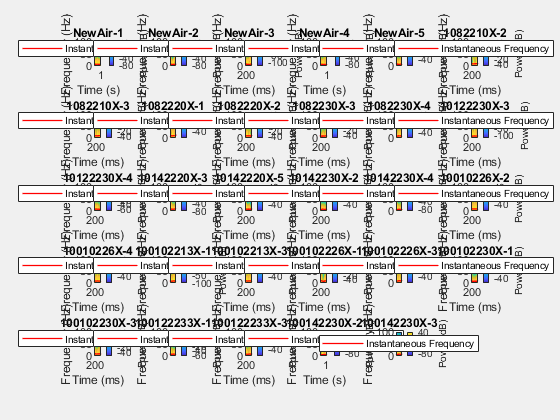

Tspeed =     6.5412
    5.0146
    3.6374
    2.4101
    1.3351
    0.4320
    0.4343
    1.0436
    1.5236
    1.8579


i = 1

Tspeed =     2.0695
    1.6291
    1.2188
    0.8388
    0.4904
    0.1837
    0.1614
    0.4068
    0.6368
    0.8396


i = 2

Tspeed =    14.1521
   10.4639
    7.1453
    4.1963
    1.6176
    0.5990
    2.4363
    3.9072
    5.0090
    5.7414


i = 3

Tspeed =     1.2023
    0.8753
    0.5950
    0.3626
    0.1821
    0.0816
    0.1109
    0.1524
    0.1592
    0.1315


i = 4

Tspeed =     8.7488
    6.5739
    4.6276
    2.9111
    1.4306
    0.3032
    0.9392
    1.7320
    2.3105
    2.6650


i = 5

Tspeed =   188.1593
  150.6163
  119.6475
   96.5905
   82.8623
   78.5260
   81.0863
   86.8338
   92.8058
   97.2000


i = 6

Tspeed =    26.4712
   34.8284
   41.6506
   46.7068
   49.9136
   51.2342
   50.6504
   48.1523
   43.7356
   37.4002


i = 7

Tspeed =   112.5326
  103.5990
   94.4401
   85.0436
   75.3982
   65.4934
   55.3204
   44.8722
   34.1476
   23.1619


i = 8

Tspeed =     4.4726
    9.2464
   18.2751
   25.9227
   31.9767
   36.4003
   39.1828
   40.3211
   39.8154
   37.6691


i = 9

Tspeed =   140.1404
  119.2123
  100.0475
   82.6450
   67.0039
   53.1226
   40.9995
   30.6327
   22.0220
   15.1737


i = 10

Tspeed =    89.8480
   88.8598
   86.8019
   83.6537
   79.3995
   74.0272
   67.5282
   59.8964
   51.1288
   41.2279


i = 11

Tspeed =     3.5239
    2.7377
    2.0571
    1.4912
    1.0634
    0.8226
    0.8057
    0.9489
    1.1602
    1.4023


i = 12

Tspeed =     0.8069
    0.8402
    0.8774
    0.9123
    0.9405
    0.9592
    0.9661
    0.9599
    0.9397
    0.9048


i = 13

Tspeed =    38.6588
   30.2682
   22.6195
   15.7141
    9.5566
    4.1732
    1.0323
    4.6311
    7.8114
   10.2727


i = 14

Tspeed =   128.1713
  108.9820
   90.9136
   73.9665
   58.1416
   43.4406
   29.8683
   17.4410
    6.2847
    4.6644


i = 15

Tspeed =     7.5288
    6.1830
    4.9502
    3.8302
    2.8229
    1.9290
    1.1517
    0.5128
    0.2960
    0.6601


i = 16

Tspeed =     7.3024
    6.1359
    5.0553
    4.0605
    3.1513
    2.3275
    1.5889
    0.9354
    0.3691
    0.1463


i = 17

Tspeed =    43.5727
   35.3551
   28.4715
   22.9854
   18.9237
   16.1911
   14.4865
   13.3347
   12.2389
   10.8056


i = 18

Tspeed =    39.1708
   33.7635
   28.5634
   23.5612
   18.7486
   14.1211
    9.6881
    5.5286
    2.4206
    4.0899


i = 19

Tspeed =     4.2125
    3.1150
    2.1963
    1.4824
    1.0320
    0.9039
    0.9975
    1.1358
    1.2426
    1.3226


i = 20

Tspeed =    28.0283
   20.7421
   14.1395
    8.2221
    3.0008
    1.6341
    5.4712
    8.6560
   11.1615
   12.9852


i = 21

Tspeed =    13.8893
   10.0656
    6.6929
    3.7763
    1.3540
    0.9155
    2.4092
    3.5307
    4.2145
    4.4539


i = 22

Tspeed =    10.1125
    7.2559
    4.6412
    2.2852
    0.5559
    1.9369
    3.5824
    5.0174
    6.2231
    7.1956


i = 23

Tspeed =    13.1361
    9.9665
    7.0959
    4.5246
    2.2544
    0.3271
    1.4169
    2.7895
    3.8680
    4.6494


i = 24

Tspeed =     6.3889
    4.3992
    2.6550
    1.1570
    0.1162
    1.1084
    1.8709
    2.3891
    2.6629
    2.6930


i = 25

Tspeed =     5.0311
    3.8061
    2.7312
    1.8212
    1.1217
    0.7741
    0.8769
    1.1455
    1.3740
    1.5067


i = 26

Tspeed =    11.6198
    8.6932
    6.0758
    3.8028
    2.0287
    1.5115
    2.4235
    3.5051
    4.4074
    5.0689


i = 27

Tspeed =    22.0995
   20.5017
   18.9310
   17.3874
   15.8710
   14.3819
   12.9202
   11.4864
   10.0809
    8.7044


i = 28

Tspeed =    27.0902
   21.6758
   16.7487
   12.3377
    8.5144
    5.4910
    3.9030
    4.3628
    5.8387
    7.3614


i = 29

ReadingPath = './data/matlabPTVinfo/';
FileName = T.Case;
OverallFreq = [];
figure('visible','on');
for i = 1:29
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(5,6,i);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift(round(length(ift)/4):round(length(ift)*3/4)));
        OverallFreq = [OverallFreq; freq];
        title(FileName{i});
        i
    end
end

## Wavelet

clear all
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
freq10 = [];
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freq10 = [freq10, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freq10oil.fig')
figure('visible','on');
clf;
freq100 = [];
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i - 12);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freq100 = [freq100, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freq100oil.fig')

figure('visible','on');
clf;
freqNewCase = [];
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,3,i - 28);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freqNewCase = [freqNewCase, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
    end
end
savefig('freqSevenNewCase.fig')
% figure('visible','on');
% clf;
% for i = 25:28
%     path = [ReadingPath, FileName{i}, '.mat'];
%     if isfile(path)
%         data = load(path);
%         traj3D = data.traj3D;
%         u = -traj3D(:,4);
%         v = traj3D(:,5);
%         w = traj3D(:,6);
%         xplot = (0:(length(u)-1))*1/200 * 1000;
%         speed = sqrt(u.^2 + v.^2 + w.^2);
%         Tspeed = sqrt(u.^2 + v.^2)
%         subplot(2,2,i - 24);
%         %cwt(Tspeed,200);
%         [ift,t] = instfreq(Tspeed,200);
%         instfreq(Tspeed,200);
%         freq = mean(ift);
%         xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(foil(i))]});
%     end
% end
% savefig('freqAir.fig')


DataPath = 'E:\PIV-PTV-oilcoatedBubbleTracking\data\matlabPTVinfo\'
figure('visible','on');
clf;
freqAir = []
for i = 1:5
    path = [DataPath, num2str(i), '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,3,i);
        %cwt(Tspeed,200);
        [ift,t] = instfreq(Tspeed,200);
        instfreq(Tspeed,200);
        freq = mean(ift);
        freqAir = [freqAir, freq];
        xlabel({['Overall freq: ', num2str(freq)],['oil fraction: ', num2str(0)]});
    end
end
savefig('freqAirNew.fig')

figure('visible','on');
clf;
foil10 = [0.08, 0.22, 0.31, 0.38, 0.49, 0.61];
foil100 = [0.05, 0.14, 0.21, 0.32, 0.43, 0.6];
freq10mean = [];
freq100mean = [];
for i = 1:6
    index = i*2 - 1;
    freq10mean = [freq10mean, (freq10(index) + freq10(index + 1))/2];
    freq100mean = [freq100mean, (freq100(index) + freq100(index + 1))/2];
end
plot(foil10, freq10mean, 'r*');
hold on;
plot(foil100, freq100mean, 'bo');
hold on;

[population2,gof] = fit(foil10',freq10mean','poly2');
plot(population2', 'r');
hold on;
[population2,gof] = fit(foil100',freq100mean','poly2');
plot(population2, 'b');

hold on;
plot([0], mean(freqAir), 'k^');

xlabel('oil fraction');
ylabel('freq');
legend('oil10', 'oil100', 'fit curve oil10', 'fit curve oil 100', 'Air bubble');
xlim([-0.1,0.75]);
ylim([3.5, 9]);
savefig('freqCompare.fig')


figure('visible','on');
clf;
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(3,4,i-12);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-100, 300]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('WaveLet100oil.fig')

figure('visible','on');
clf;
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        u = -traj3D(:,4);
        v = traj3D(:,5);
        w = traj3D(:,6);
        xplot = (0:(length(u)-1))*1/200 * 1000;
        speed = sqrt(u.^2 + v.^2 + w.^2);
        Tspeed = sqrt(u.^2 + v.^2)
        subplot(2,2,i-24);
        plot(xplot,Tspeed);
        hold on;
        plot(xplot,speed);
        hold off;
        title(FileName{i});
        xlim([0,1000]);
        ylim([-200, 400]);
        xlabel(['t (ms) ', 'foil: ', num2str(foil(i))]);
        ylabel('mm/s');
    end
end
fig = gcf;
fig.Position(3) = fig.Position(3) + 250;
Lgnd = legend('TransverseSpeed','TotalSpeed');
Lgnd.Position(1) = 0.01;
Lgnd.Position(2) = 0.4;
savefig('WaveLetAir.fig')

**Matlab run best Fit**

clear all;
Allresult = [];
T = readtable('MatLabFitData.xlsx');
ReadingPath = './data/matlabPTVinfo/';
FileName = T.Case;
Freqs = T.Freq;
As = T.A
betas = T.beta
figure('visible','on');
for i = 1:29 %length(FileNames)
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(5,6,i);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
      
       
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        if isempty(MaxID)
           MaxID = length(z); 
        end
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        %minID = min(find(t>300)); t = t(minID:end); Tdistance = Tdistance(minID:end);
        t1 = t(MinID:MaxID) - t(MinID);
        MinID = min(find(t1>200));
        tFit = t1(MinID:end);
        TFit = Tdistance(MinID:end);
        
        plot(t1, Tdistance, 'k', 'LineWidth',1);
        xlabel(FileName{i});
        
        Freq = Freqs(i);
        A = As(i);
        beta = betas(i);
        
        [fitResult, gof] = createFit(t1, Tdistance)
        fitDistance = fitResult(t1);
        hold on;
        plot(t1, fitDistance);
        result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
        Allresult = [Allresult; result];
    end
end

## transverse position amplitude

clear all;
opts = detectImportOptions('experiment_infoMatLab.csv');
ExperimentInfo = readtable('experiment_infoMatLab.csv');
ReadingPath = './data/matlabPTVinfo/';
FileName = ExperimentInfo.ID;
foil = ExperimentInfo.foil;
figure('visible','on');
clf;
freq10 = [];
for i = 1:12
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,4,i);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
        xNew = [xNew,z];
        xTable = array2table(xNew,'VariableNames',{'horizonal','z'});
        writetable(xTable, [FileName{i}, 'Project.csv']);
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        t1 = t(MinID:MaxID) - t(MinID);
        
        plot(t1, Tdistance, 'k', 'LineWidth',1);
        
        try
            [fitResult, gof] = createFit(t1, Tdistance)
            fitDistance = fitResult(t1);
            hold on;
            plot(t1, fitDistance);
            result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
            xlim([0, 800])
            ylim([-4 4])
            ylabel('Transverse distance(mm)');
            title(num2str(foil(i)))
            xlabel({sprintf('$y = %.3f\\cdot e^{%.6f\\cdot x}\\cdot sin(2\\pi\\cdot x / %.6f + 2*pi / %.3f)$', result);'t(ms)' }, 'Interpreter','latex')
        catch
        end
    end
end

savefig('TransverseSpeedAmplitude10oilTime.fig')


figure('visible','on');
clf;
freq10 = [];
for i = 13:24
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,4,i - 12);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
        xNew = [xNew,z];
        xTable = array2table(xNew,'VariableNames',{'horizonal','z'});
        writetable(xTable, [FileName{i}, 'Project.csv']);
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        t1 = t(MinID:MaxID) - t(MinID);
        
        plot(t1, Tdistance, 'k', 'LineWidth',1);
        
        try
            [fitResult, gof] = createFit(t1, Tdistance)
            fitDistance = fitResult(t1);
%             hold on;
%             plot(t1, fitDistance);
            xlim([0, 800])
            ylim([-4 4])
            result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
            ylabel('Transverse distance(mm)');
            title(num2str(foil(i)))
            xlabel({sprintf('$y = %.3f\\cdot e^{%.6f\\cdot x}\\cdot sin(2\\pi\\cdot x / %.6f + 2*pi / %.3f)$', result);'t(ms)' }, 'Interpreter','latex')
        catch
        end
        %title(FileName{i});
    end
end

fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       1.623  (1.417, 1.829)
       b =  -8.758e-14  (fixed at bound)
       c =       158.9  (156.6, 161.3)
       d =       0.675  (0.6573, 0.6928)
       e =   0.0003037  (-4.316e-05, 0.0006506)

gof = struct with fields:
           sse: 108.2043
       rsquare: 0.6014
           dfe: 141
    adjrsquare: 0.5930
          rmse: 0.8760


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       4.207  (3.621, 4.794)
       b =   -0.004408  (-0.005354, -0.003461)
       c =       261.4  (249.2, 273.7)
       d =      0.8285  (0.8076, 0.8494)
       e =   3.344e-05  (-0.0002615, 0.0003284)

gof = struct with fields:
           sse: 94.1180
       rsquare: 0.6866
           dfe: 147
    adjrsquare: 0.6780
          rmse: 0.8002


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       3.986  (3.109, 4.863)
       b =   -0.004871  (-0.00641, -0.003332)
       c =       230.5  (216, 245.1)
       d =      0.7967  (0.771, 0.8224)
       e =  -4.825e-06  (-0.0004178, 0.0004082)

gof = struct with fields:
           sse: 148.1138
       rsquare: 0.5087
           dfe: 139
    adjrsquare: 0.4946
          rmse: 1.0323


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       3.048  (2.855, 3.241)
       b =    -0.00114  (-0.001318, -0.0009621)
       c =       186.1  (185, 187.1)
       d =      0.6394  (0.635, 0.6439)
       e =    0.000241  (0.0001156, 0.0003665)

gof = struct with fields:
           sse: 21.2442
       rsquare: 0.9594
           dfe: 156
    adjrsquare: 0.9584
          rmse: 0.3690


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =        2.68  (2.139, 3.222)
       b =  -0.0005129  (-0.001018, -7.855e-06)
       c =         183  (180, 185.9)
       d =      0.6342  (0.6203, 0.6481)
       e =  -0.0004021  (-0.0008134, 9.341e-06)

gof = struct with fields:
           sse: 194.0344
       rsquare: 0.6365
           dfe: 150
    adjrsquare: 0.6268
          rmse: 1.1373


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       5.343  (4.769, 5.917)
       b =    -0.00472  (-0.005442, -0.003997)
       c =       390.4  (367.9, 413)
       d =      0.8037  (0.7879, 0.8196)
       e =   0.0001199  (-9.258e-05, 0.0003324)

gof = struct with fields:
           sse: 86.2365
       rsquare: 0.7988
           dfe: 170
    adjrsquare: 0.7941
          rmse: 0.7122


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       5.723  (5.124, 6.321)
       b =   -0.004513  (-0.005176, -0.00385)
       c =       367.1  (350, 384.2)
       d =      0.7975  (0.7839, 0.8112)
       e =   5.298e-05  (-0.0001642, 0.0002702)

gof = struct with fields:
           sse: 90.7657
       rsquare: 0.7911
           dfe: 170
    adjrsquare: 0.7862
          rmse: 0.7307


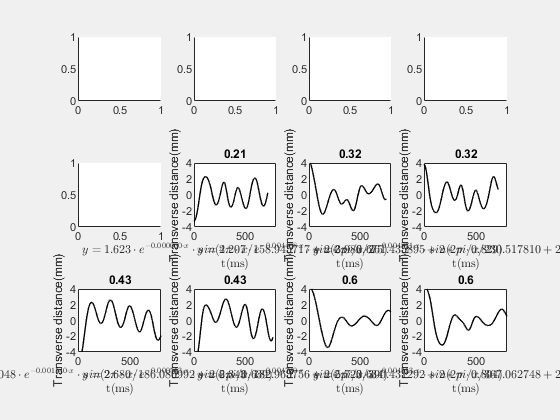

savefig('TransverseSpeedAmplitude100oilTime.fig')

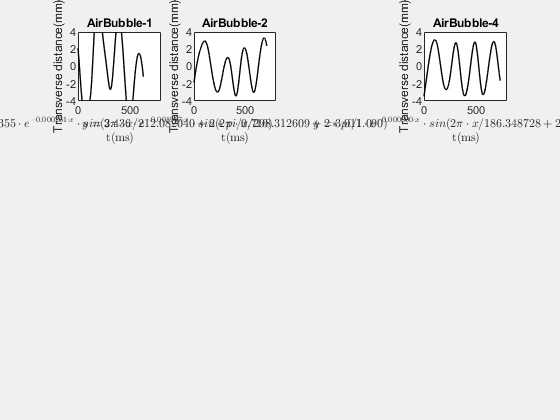

fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       6.355  (5.059, 7.651)
       b =  -0.0002609  (-0.0008282, 0.0003065)
       c =       212.1  (208.1, 216.1)
       d =      0.7159  (0.7008, 0.731)
       e =  -0.0009376  (-0.002126, 0.0002507)

gof = struct with fields:
           sse: 693.1841
       rsquare: 0.6570
           dfe: 122
    adjrsquare: 0.6458
          rmse: 2.3837


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       3.436  (2.141, 4.732)
       b =   -0.001967  (-0.003287, -0.0006464)
       c =       298.3  (281.3, 315.3)
       d =        1.09  (1.033, 1.147)
       e =   0.0005379  (-0.0002104, 0.001286)

gof = struct with fields:
           sse: 455.6947
       rsquare: 0.2243
           dfe: 138
    adjrsquare: 0.2018
          rmse: 1.8172


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       3.011  (2.844, 3.179)
       b =   -2.22e-14  (fixed at bound)
       c =       186.3  (184.9, 187.8)
       d =      0.6072  (0.6005, 0.614)
       e =  -0.0001767  (-0.0004584, 0.0001051)

gof = struct with fields:
           sse: 76.3457
       rsquare: 0.8851
           dfe: 144
    adjrsquare: 0.8827
          rmse: 0.7281


figure('visible','on');
clf;
freq10 = [];
for i = 25:28
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,4,i - 24);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
        xNew = [xNew,z];
        xTable = array2table(xNew,'VariableNames',{'horizonal','z'});
        writetable(xTable, [FileName{i}, 'Project.csv']);
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        t1 = t(MinID:MaxID) - t(MinID);
        
        plot(t1, Tdistance,'k', 'LineWidth',1);
        
        try
            [fitResult, gof] = createFit(t1, Tdistance)
            fitDistance = fitResult(t1);
%             hold on;
%             plot(t1, fitDistance);
            xlim([0, 800])
            ylim([-4 4])
            result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
            ylabel('Transverse distance(mm)');
            xlabel({sprintf('$y = %.3f\\cdot e^{%.6f\\cdot x}\\cdot sin(2\\pi\\cdot x / %.6f + 2*pi / %.3f)$', result);'t(ms)' }, 'Interpreter','latex')
        catch
        end
        title(FileName{i});
    end
end

figure('visible','on');
clf;
freq10 = [];
for i = 29:35
    path = [ReadingPath, FileName{i}, '.mat'];
    if isfile(path)
        data = load(path);
        traj3D = data.traj3D;
        Plane = data.Plane; a = Plane(1); b = Plane(2); d = Plane(3);
        x0 = 0; y0 = (d - a * x0) / b;
        x1 = 1; y1 = (d - a * x1) / b;
        vector = [x0,y0;x1,y1];
        for k = 1:length(traj3D)
            q = traj3D(k,1:2);
            p = proj(vector,q);
            traj3D(k,1:2) = p;
        end
        subplot(3,3,i - 28);
        x = traj3D(:,1); x = x - x(1);
        y = traj3D(:,2); y = y - y(1);
        z = traj3D(:,3);
        Tdistance = sqrt(x.^2 + y.^2);
        xNew = sqrt(x.^2 + y.^2);
        for k = 1:length(xNew)
            if x(k) > 0
                xNew(k) = -1 * xNew(k);
            end
        end
        xNew = [xNew,z];
        xTable = array2table(xNew,'VariableNames',{'horizonal','z'});
        writetable(xTable, [FileName{i}, 'Project.csv']);
        for k = 1:length(Tdistance)
            if x(k) > 0
                Tdistance(k) = -1 * Tdistance(k);
            end
        end
       
        MaxID = min(find(z>174));
        MinID = max(find(z<23));
        Tdistance = detrend(Tdistance(MinID:MaxID));
        t = [1:length(z)] * 5;
        t1 = t(MinID:MaxID) - t(MinID);
        
        plot(t1, Tdistance);
        
        try
            [fitResult, gof] = createFit(t1, Tdistance)
            fitDistance = fitResult(t1);
            hold on;
            plot(t1, fitDistance);
            result = [fitResult.a,fitResult.b,fitResult.c,fitResult.d];
            ylabel('Transverse distance(mm)');
            xlabel({sprintf('$y = %.3f\\cdot e^{%.6f\\cdot x}\\cdot sin(2\\pi\\cdot x / %.6f + 2*pi / %.3f)$', result);'t(ms)' }, 'Interpreter','latex')
        catch
        end
        title(FileName{i});
    end
end

fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       1.941  (1.868, 2.014)
       b =  -3.992e-14  (fixed at bound)
       c =       164.6  (163.9, 165.4)
       d =       1.033  (1.021, 1.046)
       e =  -0.0001611  (-0.0002819, -4.033e-05)

gof = struct with fields:
           sse: 14.6630
       rsquare: 0.9632
           dfe: 145
    adjrsquare: 0.9624
          rmse: 0.3180


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       2.079  (1.978, 2.18)
       b =  -0.0002808  (-0.0004044, -0.0001573)
       c =       166.5  (165.9, 167)
       d =      0.6243  (0.6211, 0.6275)
       e =    0.000242  (0.0001591, 0.0003249)

gof = struct with fields:
           sse: 6.7304
       rsquare: 0.9788
           dfe: 144
    adjrsquare: 0.9782
          rmse: 0.2162


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       3.794  (3.377, 4.212)
       b =   -0.003479  (-0.004092, -0.002866)
       c =       252.1  (244.9, 259.4)
       d =       0.602  (0.5935, 0.6106)
       e =    0.000466  (0.0002375, 0.0006946)

gof = struct with fields:
           sse: 60.7540
       rsquare: 0.7818
           dfe: 150
    adjrsquare: 0.7760
          rmse: 0.6364


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       2.239  (1.963, 2.515)
       b =  -0.0004462  (-0.000765, -0.0001273)
       c =       170.1  (168.7, 171.6)
       d =      0.8511  (0.8359, 0.8663)
       e =  -4.845e-05  (-0.0002646, 0.0001677)

gof = struct with fields:
           sse: 49.6553
       rsquare: 0.8445
           dfe: 147
    adjrsquare: 0.8403
          rmse: 0.5812


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =        6.46  (6.073, 6.847)
       b =   -0.006802  (-0.007448, -0.006156)
       c =       198.5  (193.7, 203.4)
       d =      0.8758  (0.8649, 0.8867)
       e =   -0.001158  (-0.001335, -0.0009804)

gof = struct with fields:
           sse: 28.3032
       rsquare: 0.9489
           dfe: 140
    adjrsquare: 0.9474
          rmse: 0.4496


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       2.011  (1.897, 2.125)
       b =   -2.22e-14  (fixed at bound)
       c =       155.6  (154.6, 156.6)
       d =      0.8572  (0.8435, 0.871)
       e =   0.0001326  (-4.709e-05, 0.0003123)

gof = struct with fields:
           sse: 41.5290
       rsquare: 0.8962
           dfe: 155
    adjrsquare: 0.8942
          rmse: 0.5176


fitResult =      General model:
     fitResult(x) = a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;
     Coefficients (with 95% confidence bounds):
       a =       5.973  (4.669, 7.278)
       b =   -0.006229  (-0.008194, -0.004263)
       c =       247.2  (223.9, 270.4)
       d =      0.8041  (0.774, 0.8342)
       e =  -0.0006901  (-0.001255, -0.0001249)

gof = struct with fields:
           sse: 286.2164
       rsquare: 0.5406
           dfe: 140
    adjrsquare: 0.5275
          rmse: 1.4298


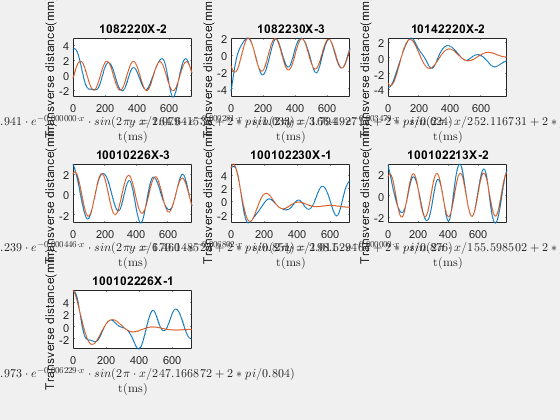

savefig('TransverseSpeedAmplitudeSevenMoreCaseTime.fig')

clear all;


function [ProjPoint] = proj(vector, q)
    p0 = vector(1,:);
    p1 = vector(2,:);
    a = [-q(1)*(p1(1)-p0(1)) - q(2)*(p1(2)-p0(2)); ...
        -p0(2)*(p1(1)-p0(1)) + p0(1)*(p1(2)-p0(2))]; 
    b = [p1(1) - p0(1), p1(2) - p0(2);...
        p0(2) - p1(2), p1(1) - p0(1)];
    ProjPoint = -(b\a);
end
function [f, P1] = findAmplitude(X, Fs)
    L = length(X);
    Y = fft(X);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
end
function result = fitDamping(x,y)
    y = detrend(y);                                                                 % Remove Linear Trend
    yu = max(y);
    yl = min(y);
    yr = (yu-yl);                                                                   % Range of ‘y’
    yz = y-yu+(yr/2);
    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                            % Returns Approximate Zero-Crossing Indices Of Argument Vector
    zt = x(zci(y));
    per = 2*mean(diff(zt));                                                         % Estimate period
    ym = mean(y);                                                                   % Estimate offset
    fit = @(b,x)  b(1) .* exp(b(2).*x) .* (sin(2*pi*x./b(3) + 2*pi/b(4))) + b(5);        % Objective Function to fit
    fcn = @(b) norm(fit(b,x) - y);    
    options = optimset('MaxFunEvals',50000, 'MaxIter', 500*500); % Least-Squares cost function
    %[result,nmrs] = fminsearch(fcn, [yr; -0.5;  per;  -1;  ym], options);
    [result,nmrs] = fminsearch(fcn, [yr; -0.5;  per;  -1;  ym], options);
end
function [fitresult, gof] = createFit(t1, Tdistance)
    %CREATEFIT(T1,TDISTANCE)
    %  Create a fit.
    %
    %  Data for 'untitled fit 1' fit:
    %      X Input : t1
    %      Y Output: Tdistance
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    
    %  Auto-generated by MATLAB on 06-Nov-2020 14:17:37
    
    
    %% Fit: 'untitled fit 1'.
    [xData, yData] = prepareCurveData( t1, Tdistance );
    
    % Set up fittype and options.
    ft = fittype( 'a*exp(b*x)*(sin(2*pi*x/c + 2*pi/d)) + e * x;', 'independent', 'x', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.DiffMinChange = 1e-11;
    opts.Display = 'Off';
    opts.Lower = [0 -0.09 0 -Inf -Inf];
    opts.MaxFunEvals = 60000;
    opts.MaxIter = 40000;
    opts.Robust = 'LAR';
    opts.StartPoint = [8 -0.007 200 0.823457828327293 -0.694828622975817];
    opts.TolFun = 1e-11;
    opts.TolX = 1e-11;
    opts.Upper = [10 0 400 Inf Inf];
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
%     % Plot fit with data.
%     figure( 'Name', 'untitled fit 1' );
%     h = plot( fitresult, xData, yData );
%     legend( h, 'Tdistance vs. t1', 'untitled fit 1', 'Location', 'NorthEast', 'Interpreter', 'none' );
%     % Label axes
%     xlabel( 't1', 'Interpreter', 'none' );
%     ylabel( 'Tdistance', 'Interpreter', 'none' );
%     grid on
end
function [px,py,pz]=projection(a,b,c,d,x,y,z)
    % given an plane equation ax+by+cz=d, project points xyz onto the plane
    % return the coordinates of the new projected points
    % written by Neo Jing Ci, 11/7/18
    A=[1 0 0 -a; 0 1 0 -b; 0 0 1 -c; a b c 0];
    B=[x; y; z; d];
    X=A\B;
    px=X(1);
    py=X(2);
    pz=X(3);
end